**Numerical Methods Final Exam 2022 - Solutions**

1. Three compression tests were carried out on a spring. In each test the displacement was measured at the same values of applied force.

The results were:

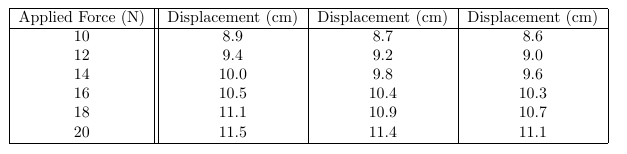

Plot the data then use linear regression to estimate the spring constant in kN/m. Plot the regression line on the same figure as the data.

% Enter solution here
forceVal = 10:2:20;
force = [forceVal, forceVal, forceVal] * 0.001;
displacement1 = [8.9, 9.4, 10.0, 10.5, 11.1, 11.5];
displacement2 = [8.7, 9.2, 9.8, 10.4, 10.9, 11.4];
displacement3 = [8.6, 9.0, 9.6, 10.3, 10.7, 11.1];
displacement = [displacement1, displacement2, displacement3] * 0.01;
fit = polyfit(displacement, force, 1);
fitPlt = polyval(fit, displacement);

disp(fit(2))

   -0.0216



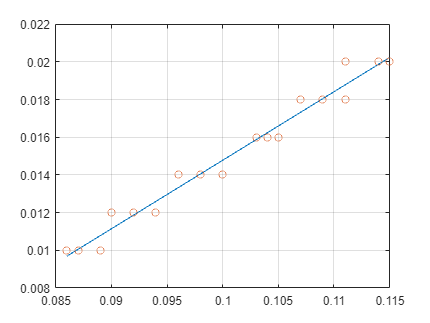


% Plot
plot(displacement, fitPlt);
hold on
plot(displacement, force, 'o');
grid on
hold off

2. The following data is to be fit to an equation of the form,

$$z = Ae^{Bx}y^C$$,

where A, B and C are constants. 

Use linearisation and regression to estimate the values of A, B, and C then use the fitted equation to estimate the value of z at the point $$(x,y) = (2.7, 3.3)$$.

Data:

% Data
x = [1 2.2 3.5 4.5 5.6 7.8];
y = [0.3 1.7 3.4 5.8 8.8 11];
z = [0.31 0.71 0.37 0.22 0.10 0.01];

% Enter solution here
% take log both side
% log(z) = log(A) + Bx + clog(y)
% find log(z), x, log(y)
logZ = log(z);
logY = log(y);
coeff = multipleLinearRegression(x', logY', logZ')

coeff =     1.5838
   -1.1920
    1.2921



% x = 1.5838
% log(y) = -1.1920
% log(Z) = 1.2921
A = coeff(1)

A = 1.5838

B = exp(coeff(2))

B = 0.3036

C = exp(coeff(3))

C = 3.6403


z = A * exp(B * 2.7) * 3.3 ^ C

z = 277.4897

3. Use a cubic **Lagrange** interpolant on the data below to estimate the following:

    a. The value of $f(x)$ when $x = 4.95$.

    b. The value of $x$ when $f(x) = 1.88$.

% Enter solution here


4. Approximate the following multiple integrals using any method (Matlab built-ins are recommended for highest accuracy):

    a. $\int\limits_{0}^{2}\int\limits_{y^3}^{4\sqrt{2y}} (x^2y - xy^2) \, dx \, dy$

    b. $\int\limits_{0}^{2}\int\limits_{0}^{4-x^2}\int\limits_{0}^{x} \sin(2z)e^{-x} \, dy \, dz \, dx$

% Enter solution here
integral2(@(y, x) x.^2.*y - x .* y .^ 2, 0, 2, @(y) y.^3, @(y) 4 .* sqrt(2.*y))

ans = 97.4315

integral3(@(z) sin(2*z)*exp(-x))

5. Answer the following questions for the integral:


$$\int\limits_{0}^{3\pi} (8 + \cos(x^2 - 3x)) \, dx$$


    a. Estimate the integral's value using 4 point Gauss-Legendre quadrature.

    b. What is the minimum number of partitions (value of $n$) needed to use Simpson's 1/3 rule to estimate the integral if we want the absolute approximate error to be less then 0.01? Demonstrate that your answer is correct.

% Enter solution here


6. The data below represents an objects position (m) measured at different times (s). Use a centred finite difference approach to estimate the time when the object experienced zero jerk.

**Reminder:** Jerk is the derivative of accelerationformul

% Enter solution here
t = 0:2:16
st = [7.2, 0.7040, 0.3040, 2.0640, 3.5840, 4.0000, 3.9840, 5.7440, 13.0240]
coeff = polyfit(t, st, 1) % measure speed coeff v = s/t

% jerk is taking 3rd derivative since distance --> Velocity -->
% Acceleration --> Jerk
% 0 jerk = constant acceleration = linear velocity = quadratic distance
% formula for improved 3rd derivative is
% -f(xi+3) + 12f(xi+2)-39f(xi+1)+56f(xi)-39f(xi-1)+12f(xi-2)-f(xi-3)/6h^4
j_cd = ( -3.984 + 12*4 - 39*3.584 + 56*2.064 - 39*0.304 + 12*0.704 - 7.2 )./(6*h.^4);



--- FUNCTIONS ---

A space to place your functions so that after running the code blocks below you can then use them in the scripts above.

function [coefficients] = multipleLinearRegression(x, y, z)
% remember to flip x, y, and z
    a = [ones(size(x)) x y]; % create matrix of 1s size x
    b = (a'*a)\(a'*z); % find coefficient
    coefficients = b;
end